clear all
syms x1(t) x2(t) y1(t) y2(t) theta1(t) theta2(t) F1x(t) F1y(t) F2x(t) F2y(t) F3x(t) F3y(t)

m1=4; m2=2;L=3; 

IG1=1/12*m1*L^2; IG2=1/12*m2*L^2;

rG1=[x1(t);y1(t)];
rG2=[x2(t);y2(t)];
F1=[F1x(t);F1y(t)];
F2=[F2x(t);F2y(t)];
F3=[F3x(t);F3y(t)];
g=9.81;

%Forces 1 and 2 act on the top arm, Force 3 on the bottom arm. 

%F=ma for top arm
eq1=m1*diff(rG1,t,t)==F1+F2-m1*g*[0;1];
MF1G1=cross(-[rG1;0],[F1;0]);
MF2G1=cross([rG1;0],[F2;0]);
%IG theta''=M for the top arm
eq2=IG1*diff(theta1(t),t,t)==MF1G1(3)+MF2G1(3);

%F=ma for the bottom arm.
eq3=m2*diff(rG2,t,t)==F3-m2*g*[0;1];
%IG theta''=M for the bototm.
MF3G2=cross(L/2*[-sin(theta2(t));cos(theta2(t));0],[F3;0]);
eq4=IG2*diff(theta2(t),t,t)==MF3G2(3);

%Keep top arm anchored at origin. 
eq5=rG1+L/2*[-sin(theta1(t));cos(theta1(t))]==[0;0];
%Keep top arm and bottom arm attached. 
eq6=rG1+L/2*[sin(theta1(t));-cos(theta1(t))]==rG2+L/2*[-sin(theta2(t));cos(theta2(t))];
%F2 and F3 must be related. 
eq7=F2==-F3;


%As usual, set up equations of motion.  NOTICE THE CONSTITUATIVE RELATION
%F2==-F3 goes in the DEs!  This is because that equation doesn't need to be
%differentiated.  Maybe we should do something about that for clarity?

DES=[eq1;eq2;eq3;eq4;eq7];
PositionConstraints=[eq5;eq6];


%Compute a snapshot in time.  Given part of the state of the system,
%compute the rest.  

completeState(DES,PositionConstraints,[],{x1==0.5,theta2==pi/4,diff(x1)==1,diff(y2)==3})

ans = struct with fields:
         F1x: -15.6577
         F2x: 17.5381
         F3x: -17.5381
         F1y: 66.9618
         F2y: -23.8750
         F3y: 23.8750
      theta1: 0.3398
      theta2: 0.7854
          x1: 0.5000
          x2: 2.0607
          y1: -1.4142
          y2: -3.8891
    Dtheta1t: 0.7071
    Dtheta2t: 2.1618
        Dx1t: 1
        Dx2t: 4.2929
        Dy1t: 0.3536
        Dy2t: 3


%Compute a snapshot in time.  Given part of the state of the system,
%compute the rest.  If the partial state presented is inconsistent, then no
%complete state can be found. Note that the prescribed values of x1 and
%theta1 don't match. 

completeState(DES,PositionConstraints,[],{x1==0.5,theta1==pi/4,diff(x1)==1,diff(y2)==3})

Error using timeStepDAESystem/selectIC (line 320)
No suitable initial value for Dtheta1t found.


Error in timeStepDAESystem (line 178)
        ICsoln=selectIC(ICsoln,hintsStruct);

Error in 

%Compute a snapshot in time.  Given part of the state of the system,
%compute the rest.  Here we are prescribing too much information, but it is
%consistent.  The solver warns us that we are probably over-determining,
%but succeeds. 

completeState(DES,PositionConstraints,[],{x1==sqrt(2)/2*3/2,theta1==pi/4,theta2==1,diff(x1)==1,diff(y2)==3})

ans = struct with fields:
         F1x: -31.7178
         F2x: 17.2246
         F3x: -17.2246
         F1y: 44.1898
         F2y: -11.9006
         F3y: 11.9006
      theta1: 0.7854
      theta2: 1
          x1: 1.0607
          x2: 3.3835
          y1: -1.0607
          y2: -2.9318
    Dtheta1t: 0.9428
    Dtheta2t: 0.7923
        Dx1t: 1
        Dx2t: 2.6421
        Dy1t: 1
        Dy2t: 3


%Compute a snapshot in time.  Given part of the state of the system,
%compute the rest.  In this example there are multiple possible
%configurations, because we are only specifying the y-coordinate of
%pendulum 1. With no diagnostics, the solver just chooses an state and goes with it. 
%if diagnostics are turned on, then the solver warns us. 

completeState(DES,PositionConstraints,[],{x1(t)==0.5,theta2==pi/4,diff(theta1(t),t)==1,diff(theta2)==0})

ans = struct with fields:
         F1x: 8.6709
         F2x: -0.9091
         F3x: 0.9091
         F1y: 33.7911
         F2y: -3.6592
         F3y: 3.6592
      theta1: 2.8018
      theta2: 0.7854
          x1: 0.5000
          x2: 2.0607
          y1: 1.4142
          y2: 1.7678
    Dtheta1t: 1
    Dtheta2t: 0
        Dx1t: -1.4142
        Dx2t: -2.8284
        Dy1t: 0.5000
        Dy2t: 1


%Turn on diagnostics to get warning. 
completeState(DES,PositionConstraints,[],{x1==0.5,theta2==pi/4,diff(theta1(t),t)==1,diff(theta2)==0},doDiagnostics=1)

The unknown functions (just the base functions, not derivatives) are:
F1x(t)
F2x(t)
F3x(t)
F1y(t)
F2y(t)
F3y(t)
theta1(t)
theta2(t)
x1(t)
x2(t)
y1(t)
y2(t)

Multiple feasible initial conditions found:
Dx1t: -1.414214    Dx2t: -2.828427    Dy1t: 0.500000    Dy2t: 1.000000    theta1: 2.801756    x2: 2.060660    y1: 1.414214    y2: 1.767767    
Dx1t: 1.414214    Dx2t: 2.828427    Dy1t: 0.500000    Dy2t: 1.000000    theta1: 0.339837    x2: 2.060660    y1: -1.414214    y2: -3.889087    

Selecting IC:
Dx1t:-1.414214    Dx2t:-2.828427    Dy1t:0.500000    Dy2t:1.000000    theta1:2.801756    x2:2.060660    y1:1.414214    y2:1.767767    
Because it is first.  Use a hint if you want to select a different initial condition.

Initial Conditions:
Y0/YP0:
F1x: 8.670894
F2x: -0.909148
F3x: 0.909148
F1y: 33.791097
F2y: -3.659250
F3y: 3.659250
theta1: 2.801756 theta1t:1.000000
theta2: 0.785398 theta2t:0.000000
x1: 0.500000 x1t:-1.414214
x2: 2.060660 x2t:-2.828427
y1: 1.414214 y1t:0.500000
y2: 1.767767 

ans = struct with fields:
         F1x: 8.6709
         F2x: -0.9091
         F3x: 0.9091
         F1y: 33.7911
         F2y: -3.6592
         F3y: 3.6592
      theta1: 2.8018
      theta2: 0.7854
          x1: 0.5000
          x2: 2.0607
          y1: 1.4142
          y2: 1.7678
    Dtheta1t: 1
    Dtheta2t: 0
        Dx1t: -1.4142
        Dx2t: -2.8284
        Dy1t: 0.5000
        Dy2t: 1


%Select the other feasibile initial condition by saying that y1 should be near -1.  
completeState(DES,PositionConstraints,[],{x1==0.5,theta2==pi/4,diff(theta1(t),t)==1,diff(theta2)==0},...
    doDiagnostics=1, hints={y1==-1})

The unknown functions (just the base functions, not derivatives) are:
F1x(t)
F2x(t)
F3x(t)
F1y(t)
F2y(t)
F3y(t)
theta1(t)
theta2(t)
x1(t)
x2(t)
y1(t)
y2(t)

Multiple feasible initial conditions found:
Dx1t: -1.414214    Dx2t: -2.828427    Dy1t: 0.500000    Dy2t: 1.000000    theta1: 2.801756    x2: 2.060660    y1: 1.414214    y2: 1.767767    
Dx1t: 1.414214    Dx2t: 2.828427    Dy1t: 0.500000    Dy2t: 1.000000    theta1: 0.339837    x2: 2.060660    y1: -1.414214    y2: -3.889087    

Selecting IC:
Dx1t:1.414214    Dx2t:2.828427    Dy1t:0.500000    Dy2t:1.000000    theta1:0.339837    x2:2.060660    y1:-1.414214    y2:-3.889087    
Because it is closest to satisfying the hints.

Initial Conditions:
Y0/YP0:
F1x: -15.314899
F2x: 11.582087
F3x: -11.582087
F1y: 61.099150
F2y: -16.814937
F3y: 16.814937
theta1: 0.339837 theta1t:1.000000
theta2: 0.785398 theta2t:0.000000
x1: 0.500000 x1t:1.414214
x2: 2.060660 x2t:2.828427
y1: -1.414214 y1t:0.500000
y2: -3.889087 y2t:1.000000
Dtheta1t: 1.000000 D

ans = struct with fields:
         F1x: -15.3149
         F2x: 11.5821
         F3x: -11.5821
         F1y: 61.0992
         F2y: -16.8149
         F3y: 16.8149
      theta1: 0.3398
      theta2: 0.7854
          x1: 0.5000
          x2: 2.0607
          y1: -1.4142
          y2: -3.8891
    Dtheta1t: 1
    Dtheta2t: 0
        Dx1t: 1.4142
        Dx2t: 2.8284
        Dy1t: 0.5000
        Dy2t: 1


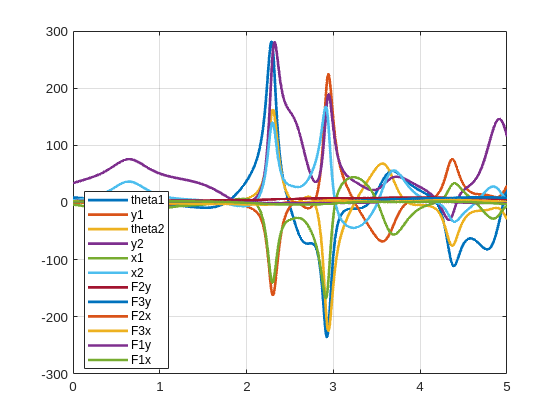


%Timestep the DAE directly.  The DEs of motion, the position constraints,
%velocity constraints, time interval, and initial conditions are not
%optional. 
soln=timeStepDAESystem(DES,PositionConstraints,[],[0,5],...
    {x1(t)==0.5,theta2==pi/4,diff(theta1(t),t)==1,"Dtheta2t==0"});

The unknown functions (just the base functions, not derivatives) are:
F1x(t)
F2x(t)
F3x(t)
F1y(t)
F2y(t)
F3y(t)
theta1(t)
theta2(t)
x1(t)
x2(t)
y1(t)
y2(t)

Multiple feasible initial conditions found:
Dx1t: -1.414214    Dx2t: -2.828427    Dy1t: 0.500000    Dy2t: 1.000000    theta1: 2.801756    x2: 2.060660    y1: 1.414214    y2: 1.767767    
Dx1t: 1.414214    Dx2t: 2.828427    Dy1t: 0.500000    Dy2t: 1.000000    theta1: 0.339837    x2: 2.060660    y1: -1.414214    y2: -3.889087    

Selecting IC:
Dx1t:-1.414214    Dx2t:-2.828427    Dy1t:0.500000    Dy2t:1.000000    theta1:2.801756    x2:2.060660    y1:1.414214    y2:1.767767    
Because it is first.  Use a hint if you want to select a different initial condition.

Initial Conditions:
Y0/YP0:
F1x: 8.670894
F2x: -0.909148
F3x: 0.909148
F1y: 33.791097
F2y: -3.659250
F3y: 3.659250
theta1: 2.801756 theta1t:1.000000
theta2: 0.785398 theta2t:0.000000
x1: 0.500000 x1t:-1.414214
x2: 2.060660 x2t:-2.828427
y1: 1.414214 y1t:0.500000
y2: 1.767767 

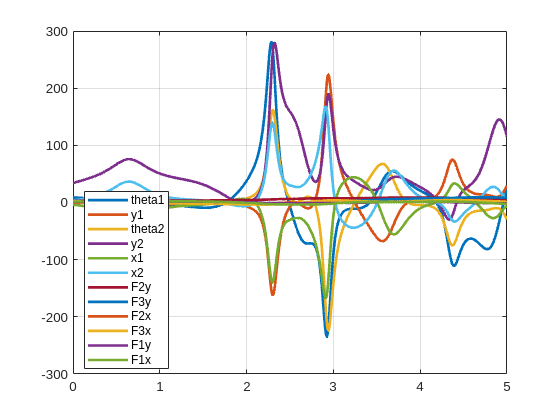


%Do the exact same thing as above, but print diagnostic information with
%the optional "doDiagnostics" option. 

soln=timeStepDAESystem(DES,PositionConstraints,[],[0,5],...
    {x1(t)==0.5,theta2==pi/4,diff(theta1(t),t)==1,"Dtheta2t==0"},doDiagnostics=1);

The unknown functions (just the base functions, not derivatives) are:
F1x(t)
F2x(t)
F3x(t)
F1y(t)
F2y(t)
F3y(t)
theta1(t)
theta2(t)
x1(t)
x2(t)
y1(t)
y2(t)

Multiple feasible initial conditions found:
Dx1t: -1.414214    Dx2t: -2.828427    Dy1t: 0.500000    Dy2t: 1.000000    theta1: 2.801756    x2: 2.060660    y1: 1.414214    y2: 1.767767    
Dx1t: 1.414214    Dx2t: 2.828427    Dy1t: 0.500000    Dy2t: 1.000000    theta1: 0.339837    x2: 2.060660    y1: -1.414214    y2: -3.889087    

Selecting IC:
Dx1t:1.414214    Dx2t:2.828427    Dy1t:0.500000    Dy2t:1.000000    theta1:0.339837    x2:2.060660    y1:-1.414214    y2:-3.889087    
Because it is closest to satisfying the hints.

Initial Conditions:
Y0/YP0:
F1x: -15.314899
F2x: 11.582087
F3x: -11.582087
F1y: 61.099150
F2y: -16.814937
F3y: 16.814937
theta1: 0.339837 theta1t:1.000000
theta2: 0.785398 theta2t:0.000000
x1: 0.500000 x1t:1.414214
x2: 2.060660 x2t:2.828427
y1: -1.414214 y1t:0.500000
y2: -3.889087 y2t:1.000000
Dtheta1t: 1.000000 D

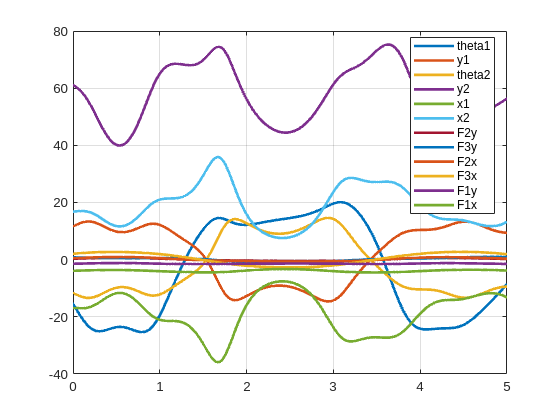

%In the example above, there was more than one feasible initial condition.
%Indicate which one to use using the option hints=

soln=timeStepDAESystem(DES,PositionConstraints,[],[0,5],...
    {x1(t)==0.5,theta2==pi/4,diff(theta1(t),t)==1,"Dtheta2t==0"},doDiagnostics=1,hints={y1==-1});

%Turn off the automatic plotting using the optional doPlot= option

soln=timeStepDAESystem(DES,PositionConstraints,[],[0,5],...
    {x1(t)==0.5,theta2==pi/4,diff(theta1(t),t)==1,"Dtheta2t==0"},hints={y1==-1},doPlot=0);


%Select the DAE solver to use.  Sometimes one solver will work and another
%won't. Options are "ode15s","ode23t","ode15i". 

soln=timeStepDAESystem(DES,PositionConstraints,[],[0,5],...
    {x1(t)==0.5,theta2==pi/4,diff(theta1(t),t)==1,"Dtheta2t==0"},hints={y1==-1},doPlot=0,solver="ode23t");
solnDAE=soln;

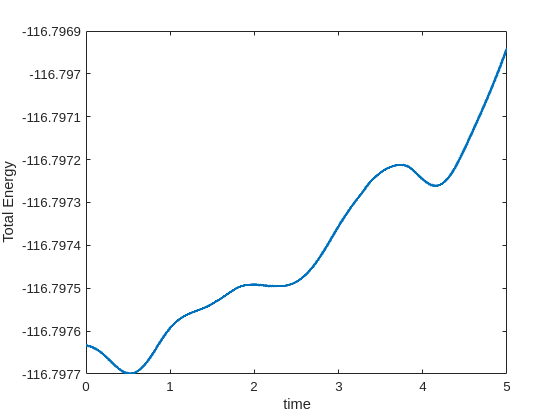




%See if we are conserving energy. 
KineticEnergy=1/2*m1*(soln.Dx1t.^2+soln.Dy1t.^2)+1/2*m2*(soln.Dx2t.^2+soln.Dy2t.^2)...
    +1/2*IG1*soln.Dtheta1t.^2+1/2*IG2*soln.Dtheta2t.^2;
PotentialEnergy=m1*soln.y1*g+m2*soln.y2*g;
plot(soln.t,KineticEnergy+PotentialEnergy,'LineWidth',2)
xlabel('time'); ylabel('Total Energy')

%Get a general set of governing equations. 
clear m1 m2 L g
syms m1 m2 L g
eq1=m1*diff(rG1,t,t)==F1+F2-m1*g*[0;1];
MF1G1=cross(-[rG1;0],[F1;0]);
MF2G1=cross([rG1;0],[F2;0]);
%IG theta''=M for the top arm
eq2=IG1*diff(theta1(t),t,t)==MF1G1(3)+MF2G1(3);

%F=ma for the bottom arm.
eq3=m2*diff(rG2,t,t)==F3-m2*g*[0;1];
%IG theta''=M for the bototm.
MF3G2=cross(L/2*[-sin(theta2(t));cos(theta2(t));0],[F3;0]);
eq4=IG2*diff(theta2(t),t,t)==MF3G2(3);

%Keep top arm anchored at origin. 
eq5=rG1+L/2*[-sin(theta1(t));cos(theta1(t))]==[0;0];
%Keep top arm and bottom arm attached. 
eq6=rG1+L/2*[sin(theta1(t));-cos(theta1(t))]==rG2+L/2*[-sin(theta2(t));cos(theta2(t))];
%F2 and F3 must be related. 
eq7=F2==-F3;

DES=[eq1;eq2;eq3;eq4;eq7];
PositionConstraints=[eq5;eq6];

[governingEqs,PPs]=generateGoverningDEs(DES,PositionConstraints,[],[theta1,diff(theta1),theta2,diff(theta2)]);
governingEqs

$$governingEqs = \begin{array}{l} \left(\begin{array}{c} \frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)=-\frac{2\,L\,\left(6\,g\,m_{1}\,\sin\left(\theta_{1}\left(t\right)\right)+12\,g\,m_{2}\,\sin\left(\theta_{1}\left(t\right)\right)+6\,L\,m_{2}\,\sigma_{1}\,\sigma_{3}+L^{2}\,g\,{m_{2}}^{2}\,\sin\left(\theta_{1}\left(t\right)-2\,\theta_{2}\left(t\right)\right)+L^{3}\,{m_{2}}^{2}\,\sin\left(\sigma_{6}\right)\,\sigma_{2}+L^{2}\,g\,{m_{2}}^{2}\,\sin\left(\theta_{1}\left(t\right)\right)+L^{3}\,{m_{2}}^{2}\,\sigma_{1}\,\sigma_{3}+L^{2}\,g\,m_{1}\,m_{2}\,\sin\left(\theta_{1}\left(t\right)\right)\right)}{\sigma_{5}}\\ \frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)=\frac{2\,L\,m_{2}\,\left(12\,L\,\sigma_{1}\,\sigma_{2}-12\,g\,\sin\left(\theta_{2}\left(t\right)\right)-2\,L^{2}\,g\,m_{2}\,\sin\left(\theta_{2}\left(t\right)\right)+L^{2}\,g\,m_{1}\,\sigma_{4}+2\,L^{2}\,g\,m_{2}\,\sigma_{4}+L^{3}\,m_{1}\,\sigma_{1}\,\sigma_{2}+4\,L^{3}\,m_{2}\,\sigma_{1}\,\sigma_{2}+L^{3}\,m_{2}\,\sin\left(\sigma_{6}\right)\,\sigma_{3}\right)}{\sigma_{5}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}\\ \sigma_{3}={\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}\\ \sigma_{4}=\sin\left(2\,\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)\\ \sigma_{5}=6\,L^{2}\,m_{1}+36\,L^{2}\,m_{2}+2\,L^{4}\,{m_{2}}^{2}-2\,L^{4}\,{m_{2}}^{2}\,\cos\left(\sigma_{6}\right)+L^{4}\,m_{1}\,m_{2}+72\\ \sigma_{6}=2\,\theta_{1}\left(t\right)-2\,\theta_{2}\left(t\right) \end{array}$$

%Do the same as above, but print diagnostic information using the
%doDiagnostics option
[governingEqs,PPs]=generateGoverningDEs(DES,PositionConstraints,[],[theta1,diff(theta1),theta2,diff(theta2)],doDiagnostics=1);

The unknown functions are:
F1x(force)
F2x(force)
F3x(force)
F1y(force)
F2y(force)
F3y(force)
theta1
theta2
x1
x2
y1
y2

Expected Number of State Variables:4


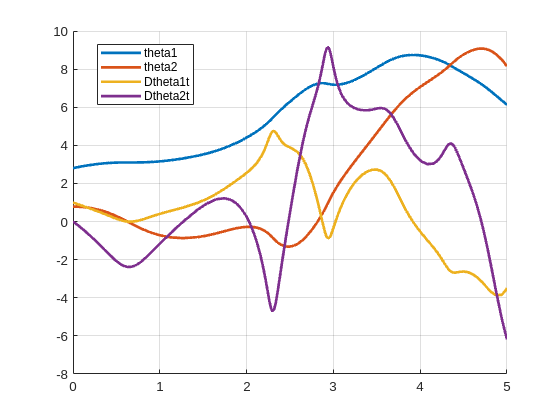



%Plug in the same m1, m2, L, g from above, use the timestepper to see if we
%match results with the DAE solver.  

params.m1=4;
params.m2=2;
params.L=3;
params.g=9.81;

specificGoverningEqns=subs(governingEqs,params);
specificPPs=subs(PPs,params);

soln=timeStepODESystem(specificGoverningEqns,[0,5],{theta1==pi-asin(0.5*2/3),theta2==pi/4,diff(theta1(t),t)==1,"Dtheta2t==0"});

soln

soln = struct with fields:
            t: [134×1 double]
       theta1: [134×1 double]
       theta2: [134×1 double]
     Dtheta1t: [134×1 double]
     Dtheta2t: [134×1 double]
    Dtheta1tt: [134×1 double]
    Dtheta2tt: [134×1 double]


%The solution above does not contain any information about x1, x2, etc,
%because we only provided differential equations in terms of theta.  If we
%want further information, specify the "post-processing equations" using
%PostProcessFunctions=
soln=timeStepODESystem(specificGoverningEqns,[0,5],{theta1==pi-asin(0.5*2/3),theta2==pi/4,diff(theta1(t),t)==1,"Dtheta2t==0"},...
    PostProcessFunctions=specificPPs);


soln

soln = struct with fields:
            t: [134×1 double]
       theta1: [134×1 double]
       theta2: [134×1 double]
     Dtheta1t: [134×1 double]
     Dtheta2t: [134×1 double]
    Dtheta1tt: [134×1 double]
    Dtheta2tt: [134×1 double]
         Dx1t: [134×1 double]
         Dx2t: [134×1 double]
        Dx1tt: [134×1 double]
        Dx2tt: [134×1 double]
         Dy1t: [134×1 double]
         Dy2t: [134×1 double]
        Dy1tt: [134×1 double]
        Dy2tt: [134×1 double]
          F1x: [134×1 double]
          F2x: [134×1 double]
          F3x: [134×1 double]
          F1y: [134×1 double]
          F2y: [134×1 double]
          F3y: [134×1 double]
           x1: [134×1 double]
           x2: [134×1 double]
           y1: [134×1 double]
           y2: [134×1 double]


solnODE=soln;


%Do the same as above, but don't automatically plot things. 

soln=timeStepODESystem(specificGoverningEqns,[0,5],{theta1==pi-asin(0.5*2/3),theta2==pi/4,diff(theta1(t),t)==1,"Dtheta2t==0"},...
    PostProcessFunctions=specificPPs,doPlot=0);


The unknown functions (just the base functions, not derivatives) are:
theta1(t),
theta2(t)



%Do the same as above, but print diagnostic information with the optional
%doDiagnostics= option. 
%Do the same as above, but automatically plot things. 
%The solution above does not contain any information about x1, x2, etc,
%because we only provided differential equations in terms of theta.  If we
%want further information, specify the "post-processing equations" using
%PostProcessFunctions=
soln=timeStepODESystem(specificGoverningEqns,[0,5],{theta1==pi-asin(0.5*2/3),theta2==pi/4,diff(theta1(t),t)==1,"Dtheta2t==0"},...
    PostProcessFunctions=specificPPs,doDiagnostics=1);

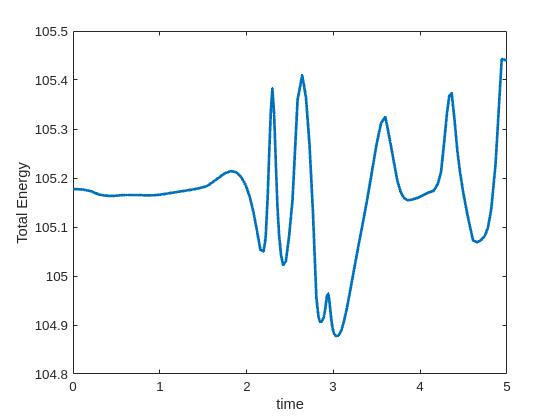

%Note that this is still close-ish to conserving energy, but is actually
%worse at it. Less than 1% off, though. 
KineticEnergy=subs(1/2*m1*(soln.Dx1t.^2+soln.Dy1t.^2)+1/2*m2*(soln.Dx2t.^2+soln.Dy2t.^2)+...
    1/2*IG1*soln.Dtheta1t.^2+1/2*IG2*soln.Dtheta2t.^2,{m1,m2,L},{4,2,3});
PotentialEnergy=subs(m1*soln.y1*g+m2*soln.y2*g,{m1,m2,L,g},{4,2,3,9.81});
plot(soln.t,KineticEnergy+PotentialEnergy,'LineWidth',2)
xlabel('time'); ylabel('Total Energy')

%Check and make sure that the DAE solver and the ODE solver give us the
%same results. 


solnDAE=timeStepDAESystem(subs(DES,params),subs(PositionConstraints,params),[],[0,5],...
    {theta1==0.5,theta2==pi/4,diff(theta1(t),t)==1,"Dtheta2t==0"},doPlot=0,solver="ode23t",AbsTol=1e-10,RelTol=1e-5);


solnODE=timeStepODESystem(specificGoverningEqns,[0,5],{theta1==0.5,theta2==pi/4,diff(theta1)==1,diff(theta2)==0},doPlot=0,PostProcessFunctions=specificPPs,AbsTol=1e-10, RelTol=1e-5);


max difference in t: 0.000000


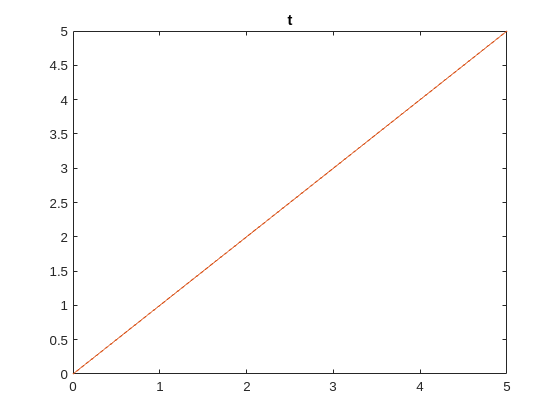

max difference in theta1: 0.000078


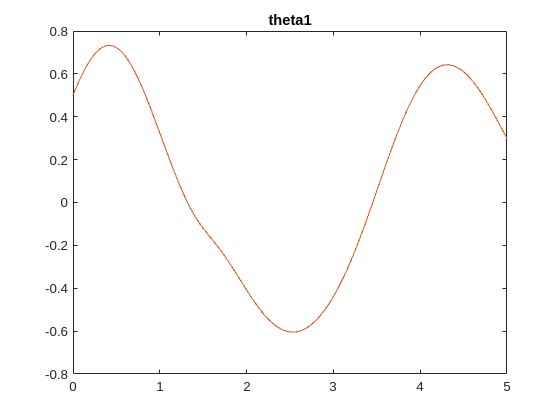

max difference in theta2: 0.000110


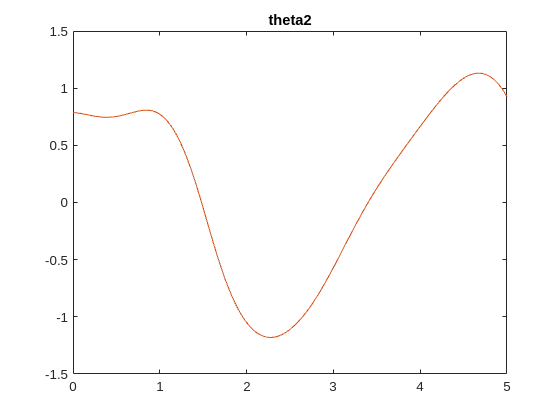

max difference in Dtheta1t: 0.000200


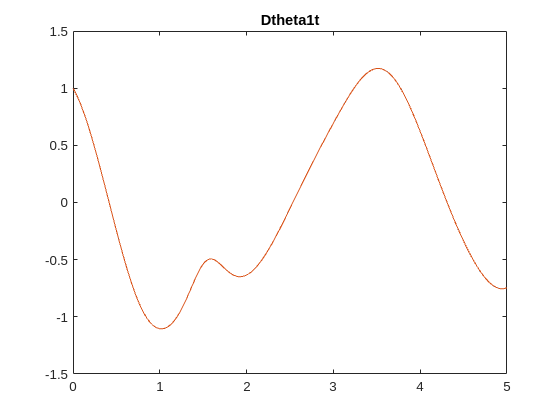

max difference in Dtheta2t: 0.000361


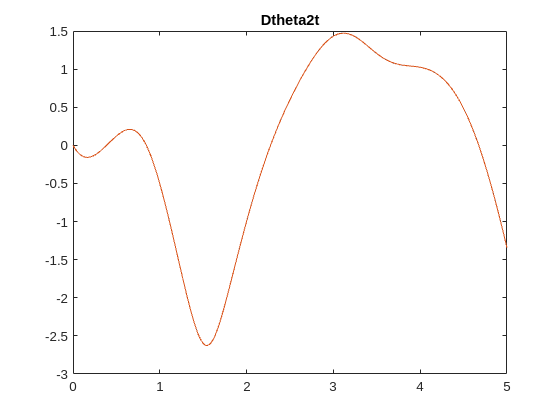

max difference in Dtheta1tt: 0.000816


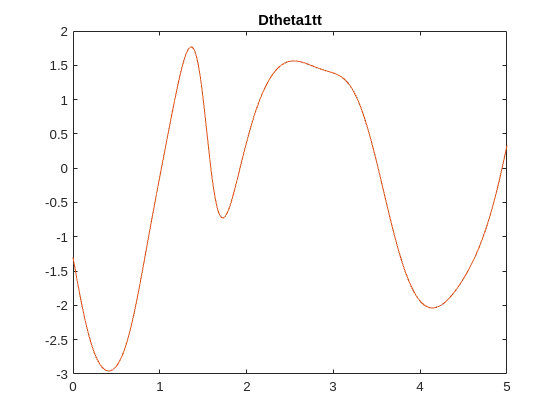

max difference in Dtheta2tt: 0.001731


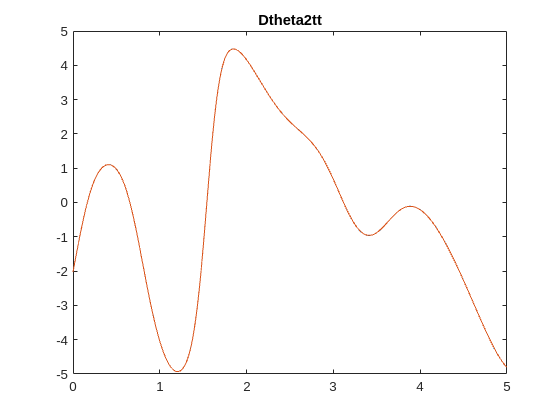

max difference in Dx1t: 0.000271


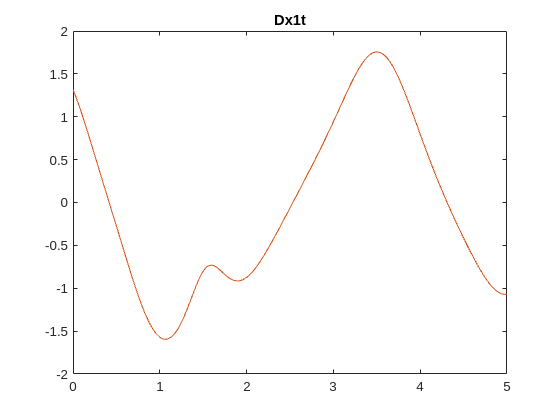

max difference in Dx2t: 0.000208


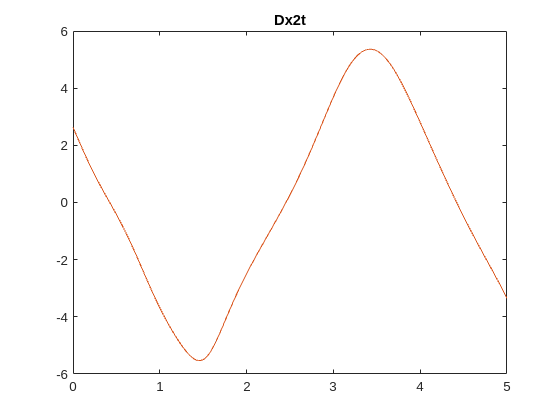

max difference in Dx1tt: 0.001252


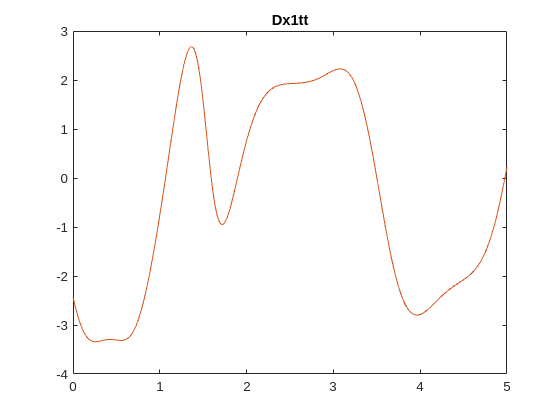

max difference in Dx2tt: 0.000918


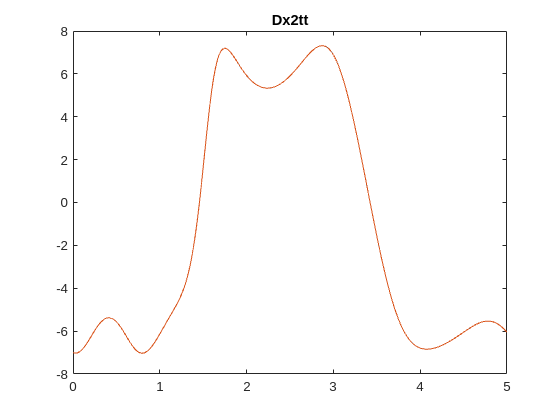

max difference in Dy1t: 0.000208


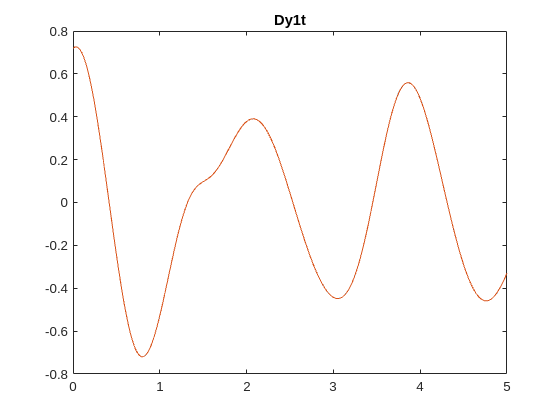

max difference in Dy2t: 0.000341


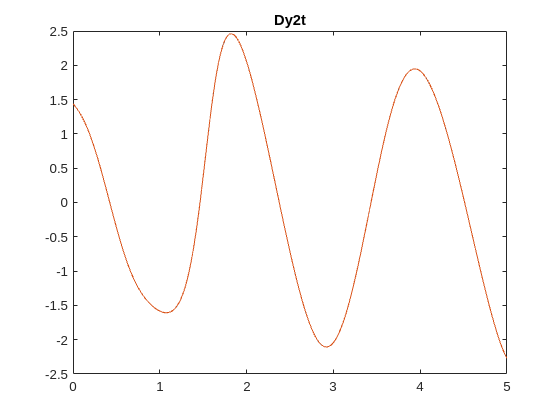

max difference in Dy1tt: 0.000739


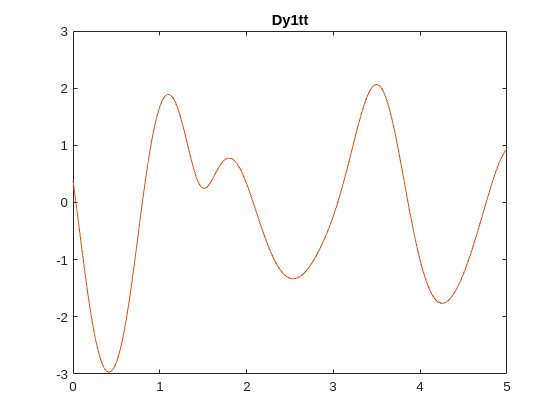

max difference in Dy2tt: 0.001490


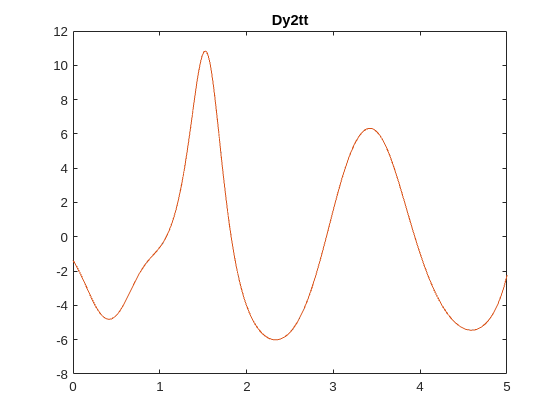

max difference in F1x: 0.004503


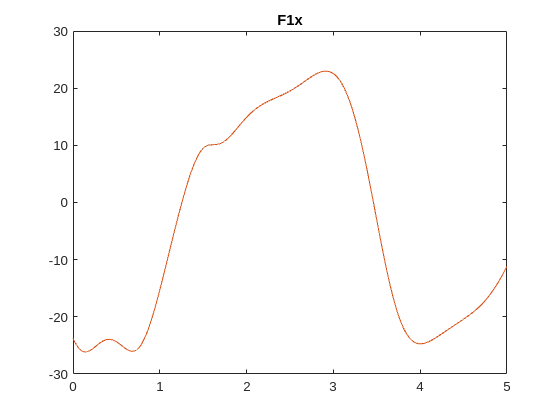

max difference in F2x: 0.001837


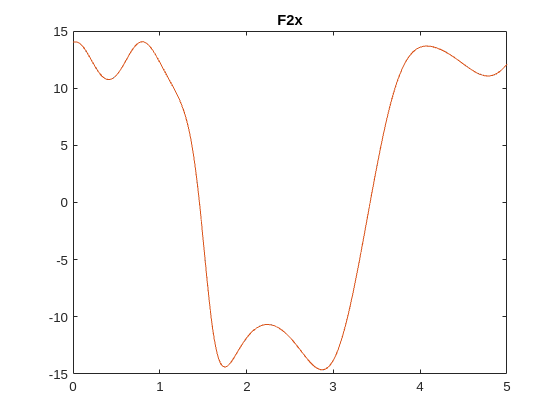

max difference in F3x: 0.001837


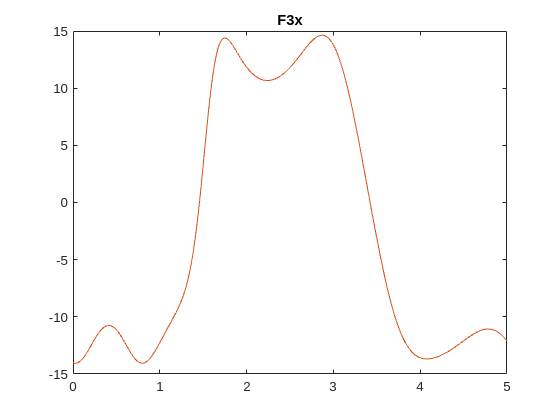

max difference in F1y: 0.002810


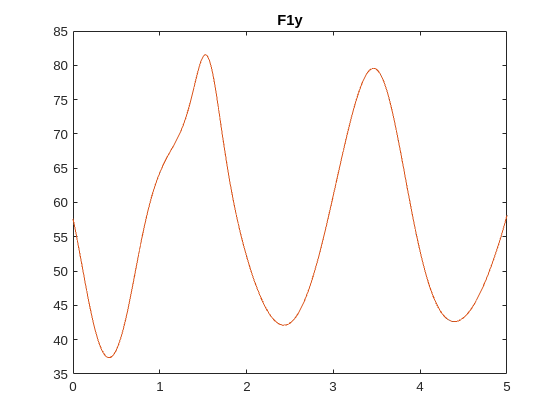

max difference in F2y: 0.002980


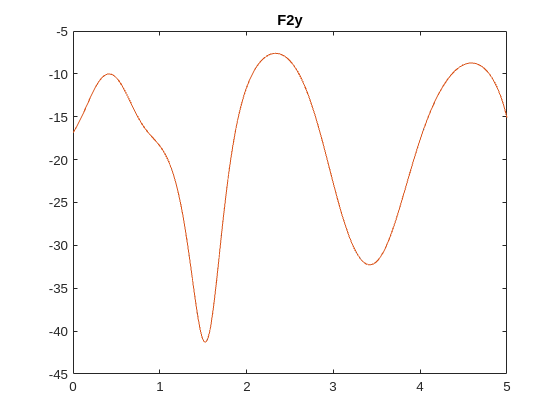

max difference in F3y: 0.002980


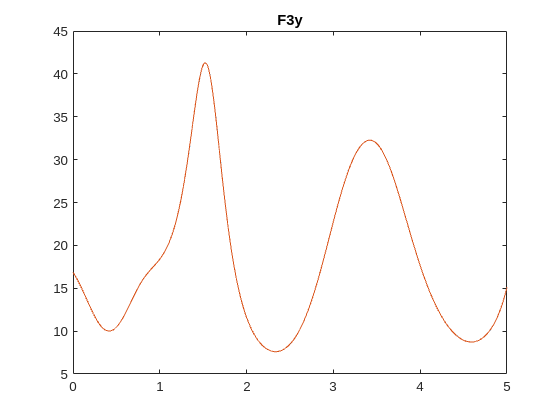

max difference in x1: 0.000082


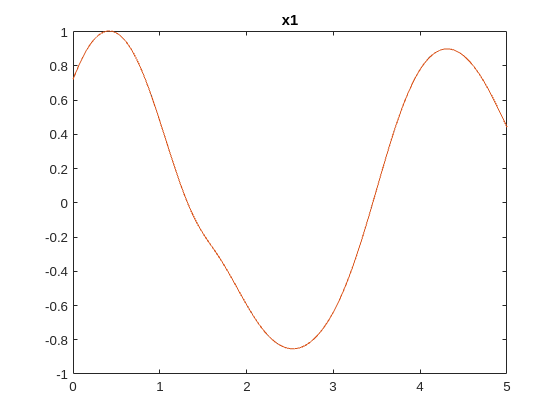

max difference in x2: 0.000146


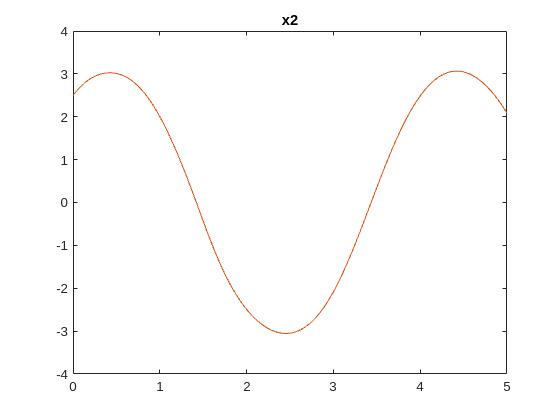

max difference in y1: 0.000143


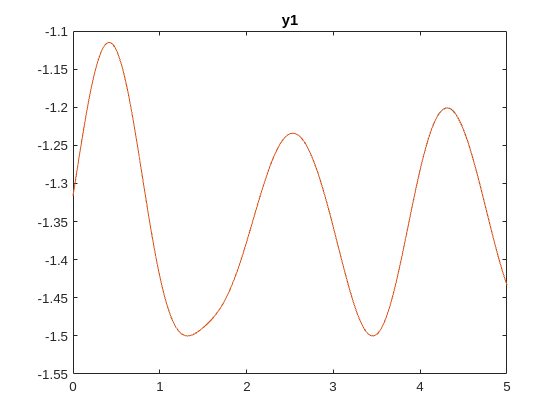

max difference in y2: 0.000539


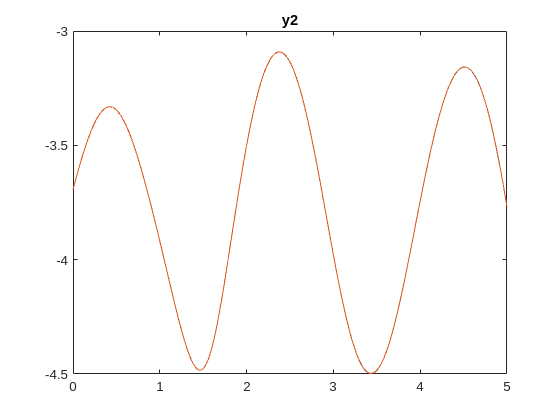


%loop over each field, compute a spline of the data field. Take the max
%over the interval [0,5].

flds=fieldnames(solnODE);
ts=linspace(0,5,1e3);
for i=1:numel(flds)
    fld=flds{i};

    splineODE=spline(solnODE.t,solnODE.(fld),ts);
    splineDAE=spline(solnDAE.t,solnDAE.(fld),ts);
    
    figure()
    plot(ts,splineODE,ts,splineDAE)
    fprintf("max difference in %s: %f\n",fld,max(abs(splineODE-splineDAE)))
    title(fld)
end